# FacTRK Test

In this notebook, we're testing an implementation of Factorized Tensor Randomized Kaczmarz.

addpath('../tproduct toolbox 2.0 (transform)/')

First, we'll generate a tensor linear system.

%fixed:
p = 7;
n = 5;

% X_true is 20 x 10 x 30
%m determines whether A = UV is underdetermined or overdetermined
%m_1 determinex whether V is underdetermined or overdetermined
%m_2 is like k in Ma & Needell's paper
m_2 = 10;

%V underdetermined (m_1 > m_2), A overdetermined (m >= 20)--Works
%m = 20;
%m = 30;
m = 40;
m_1 = 5;

%V underdetermined (m_1 > m_2), A underdetermined (m < 20)--Doesn't Works
%m = 10;
%m = 15;%
%m_1 = 5;

%V overdetermined (m_1 < m_2), A overdetermined (m > 20)--Doesn't work
% m = 20;
% m = 30;
%m = 40;
%m_1 = 12;

%generate tensors
U = randn(m, m_2,p);
V = randn(m_2,m_1,p);
A=tprod(U,V); 

X_true = randn(m_1,n,p);


%generate consistent measurements
B = tprod(A, X_true);


%generate equivalent matrix system
[matU,matV, matB,matX_true] = matricization_factorized(U,V,B,X_true);


Now, let's test the implementation of tRGS.

%run some iterations of FacTRK
X_0 = zeros(m_1,n,p);
num_its = 10000;
[~,its] = tRK_t_prod(U,V,B,X_0,num_its);
X_ln = tprod(tpinv(A),B);

%run some iterations of Factorized RK for matrices
[~,mat_its] = tRK_t_prod(matU, matV, matB, zeros(m_1*p,n,1),num_its);
matX_ln = tprod(tpinv(matU*matV),matB);

%record errors
errs = [];
res_errs = [];
ln_errs = [];
for j = 1:num_its+1
    est = its{j} - X_true;
    res_est = tprod(A,est);
    ln_est = its{j} - X_ln;
    errs = [errs,norm(est(:))];
    res_errs = [res_errs,norm(res_est(:))];
    ln_errs = [ln_errs,norm(ln_est(:))];
end

%record matrix system errors
matA = tprod(matU,matV);
mat_errs = [];
mat_res_errs = [];
mat_ln_errs = [];
for j = 1:num_its+1
    mat_est = mat_its{j} - matX_true;
    mat_res_est = tprod(matA,mat_est);
    mat_ln_est = mat_its{j} - matX_ln;
    mat_errs = [mat_errs,norm(mat_est(:))];
    mat_res_errs = [mat_res_errs,norm(mat_res_est(:))];
    mat_ln_errs = [mat_ln_errs,norm(mat_ln_est(:))];
end

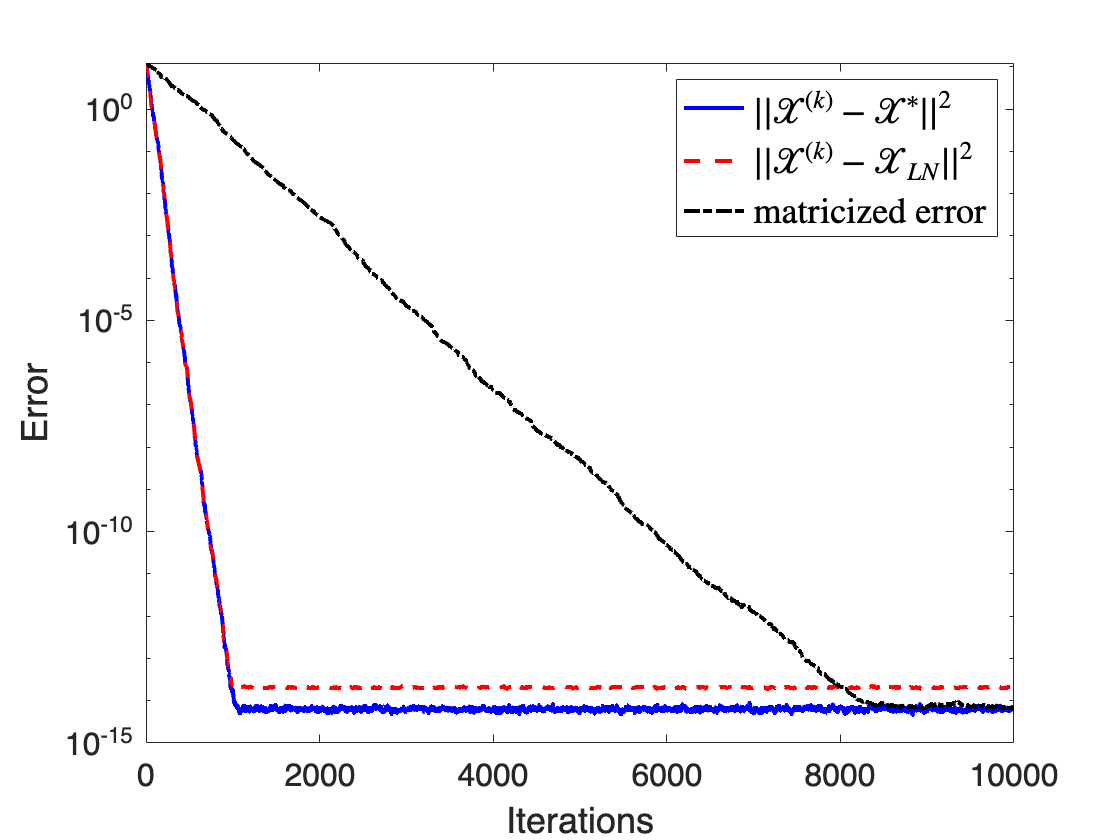

%plot errors vs iterations
figure(1);
semilogy(0:num_its,errs,'b-',0:num_its,ln_errs,'r--',0:num_its,mat_errs,'k-.','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||^2$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||^2$','matricized error','Interpreter','latex','FontSize',18)
hold off

saveas(gca,"absolute_error_FacTRKvsMatricizedRK.png");

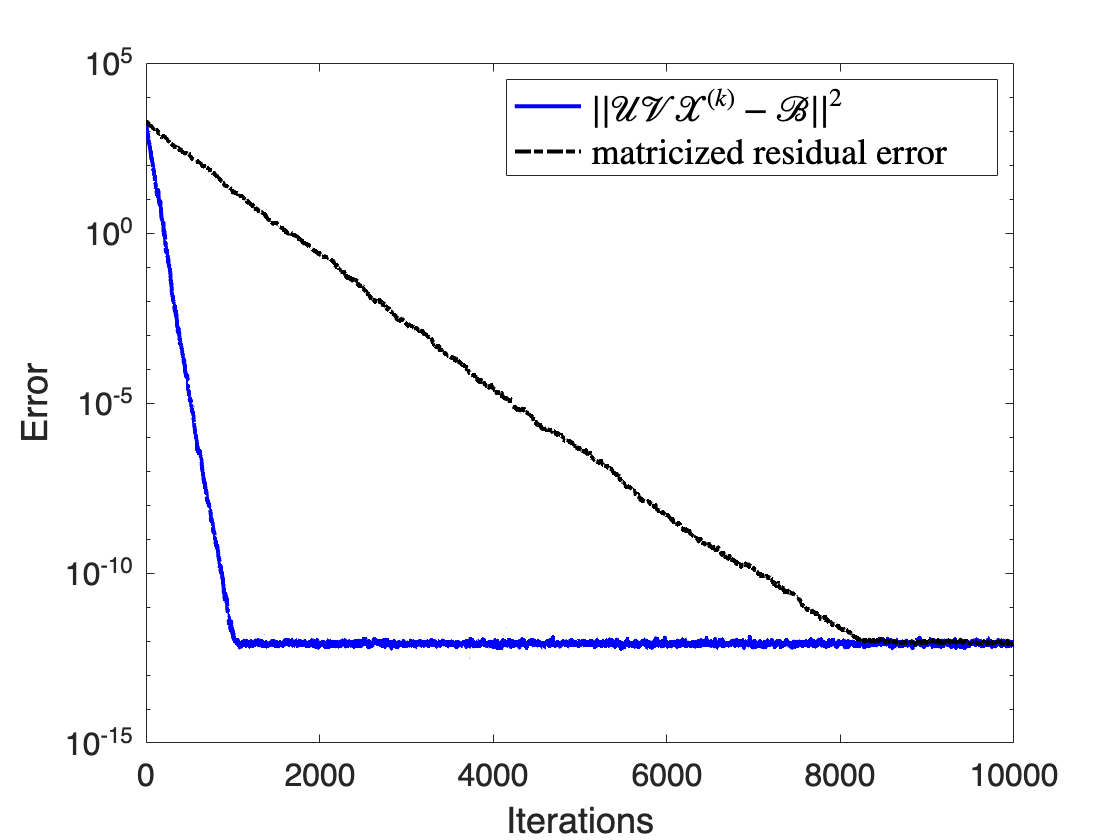

%plot residual errors vs iterations
figure(2);
semilogy(0:num_its,res_errs,'b-',0:num_its,mat_res_errs,'k-.','LineWidth',2)
hold on
set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{UV} \mathcal{X}^{(k)} - \mathcal{B}||^2$','matricized residual error', 'Interpreter','latex','FontSize',18)
hold off
saveas(gca,"residual_error_FacTRKvsMatricizedRK.png");